# simulated ecg

f1 = figure('Name','SAMPLE 01');
f2 = figure('Name','SAMPLE 02');
f3 = figure('Name','SAMPLE 03');

2秒分(1000samples)のプロットを比較

xa = linspace(1,30000,30000);
xp = linspace(1,1000,1000);

同時samplingなのでdataをalignする必要は無い

yf01a = humfas01;
ya01a = humagp01;
yf02a = humfas02;
ya02a = humagp02;
yf03a = humfas03;
ya03a = humagp03;

yf01p = humfas01(10001:11000);
ya01p = humagp01(10001:11000);
yf02p = humfas02(10001:11000);
ya02p = humagp02(10001:11000);
yf03p = humfas03(10001:11000);
ya03p = humagp03(10001:11000);

レベルの違いを吸収するために正規化

yf01a = normalize(yf01a);
ya01a = normalize(ya01a);
yf02a = normalize(yf02a);
ya02a = normalize(ya02a);
yf03a = normalize(yf03a);
ya03a = normalize(ya03a);

yf01p = normalize(yf01p);
ya01p = normalize(ya01p);
yf02p = normalize(yf02p);
ya02p = normalize(ya02p);
yf03p = normalize(yf03p);
ya03p = normalize(ya03p);

plot

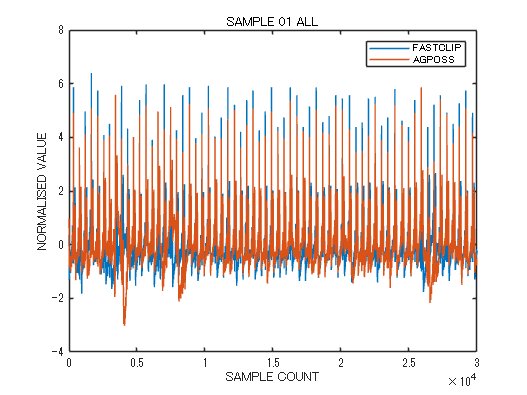

figure(f1);
plot(xa, yf01a, xa, ya01a)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 01 ALL");

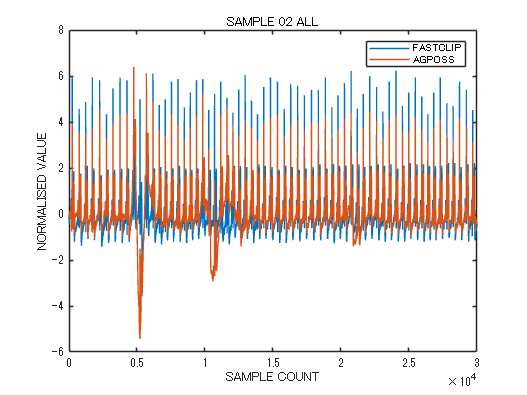

figure(f2);
plot(xa, yf02a, xa, ya02a)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 02 ALL");

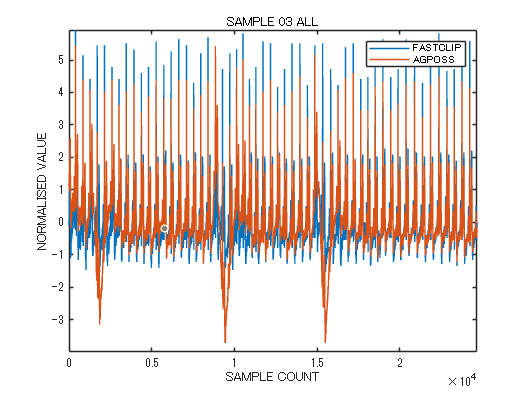

figure(f3);
plot(xa, yf03a, xa, ya03a)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 03 ALL");

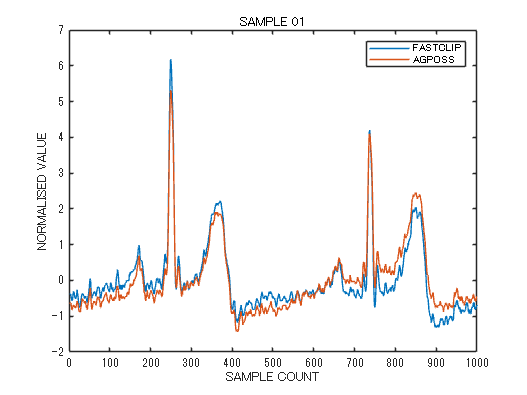

figure(f1);
plot(xp, yf01p, xp, ya01p)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 01");

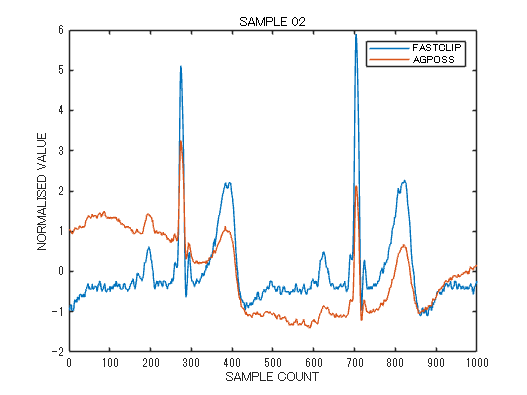

figure(f2);
plot(xp, yf02p, xp, ya02p)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 02");

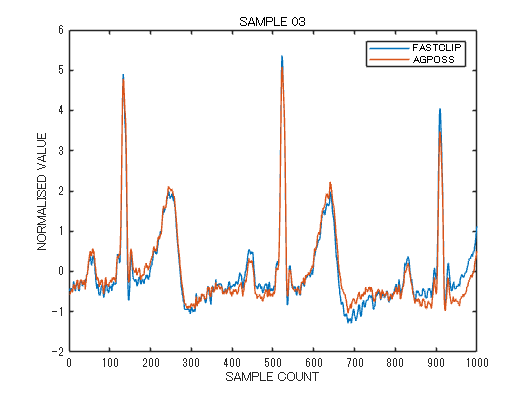

figure(f3);
plot(xp, yf03p, xp, ya03p)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 03");

**correlation coefficients**

**all**

1

corrcoef(yf01a,ya01a)

ans =     1.0000    0.8188
    0.8188    1.0000


2

corrcoef(yf02a,ya02a)

ans =     1.0000    0.7634
    0.7634    1.0000


3

corrcoef(yf03a,ya03a)

ans =     1.0000    0.8433
    0.8433    1.0000


**partial**

1

corrcoef(yf01p,ya01p)

ans =     1.0000    0.9476
    0.9476    1.0000


2

corrcoef(yf02p,ya02p)

ans =     1.0000    0.4373
    0.4373    1.0000


3

corrcoef(yf03p,ya03p)

ans =     1.0000    0.9742
    0.9742    1.0000


4

corrcoef(ya02p,ya03p)

ans =     1.0000    0.0522
    0.0522    1.0000
